# `Comparando los Datos`

### `Cargando Datos`

En primer lugar cargamos los dos archivos donde guardamos las tablas de datos anteriormente creados.

directorio_raiz ='/home/desk-chaguarma/Documents/UNI/SAG/PRACTICAS/PR1/'; 
directorio_datos = 'SALIDA/';
directorio_diag= 'DIAGRAMAS/';

pathe_diag=[directorio_raiz directorio_diag]

pathe_diag = '/home/desk-chaguarma/Documents/UNI/SAG/PRACTICAS/PR1/DIAGRAMAS/'


load([directorio_raiz directorio_datos 'tablaImprecisosActualizado.mat'])
load([directorio_raiz directorio_datos 'tablaPrecisosActualizado.mat'])

size(tablaI)

ans =        11320           7


size(tablaP)

ans =         9709           7


Al tener más datos imprecisos que precisos, no haremos la diferencia de los datos. Simplemente, mostraremos superpuestas ambas gráficas.

### Polo X respecto al tiempo

En primer lugar comparamos las gráficas de la posición X del polo, y no apreciamos ninguna variación.

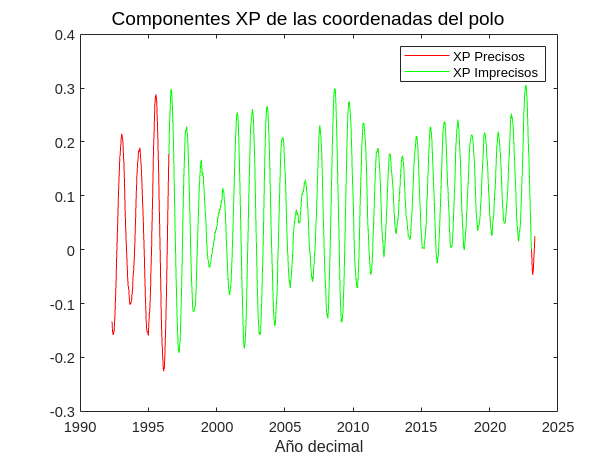

figure;
plot(tablaI.Fecha,tablaI.X,"red")
hold on
plot(tablaP.Fecha,tablaP.X,"green")
legend("XP Precisos","XP Imprecisos")
xlabel('Año decimal')
sgtitle('Componentes XP de las coordenadas del polo')
hold off

Sin embargo, si en la gráfica anterior nos acercamos lo suficiente, vemos pequeñas diferencias entre los datos.

### Polo Y respecto al tiempo

Lo siguiente es comparar la posición Y del polo, y como antes no observamos ninguna diferencia.

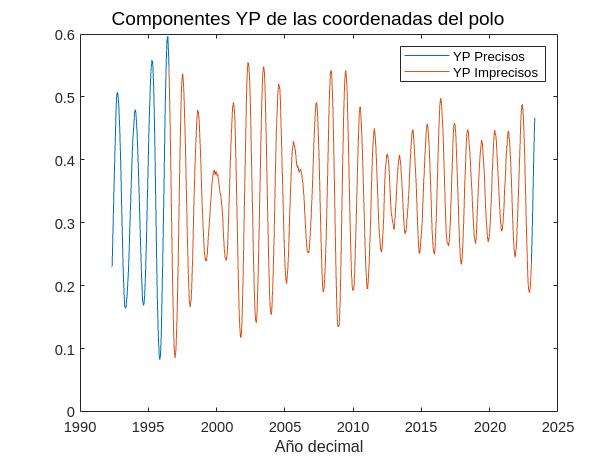

figure;
plot(tablaI.Fecha,tablaI.Y)
hold on
plot(tablaP.Fecha,tablaP.Y)
legend("YP Precisos","YP Imprecisos")
xlabel('Año decimal')
sgtitle('Componentes YP de las coordenadas del polo')
hold off

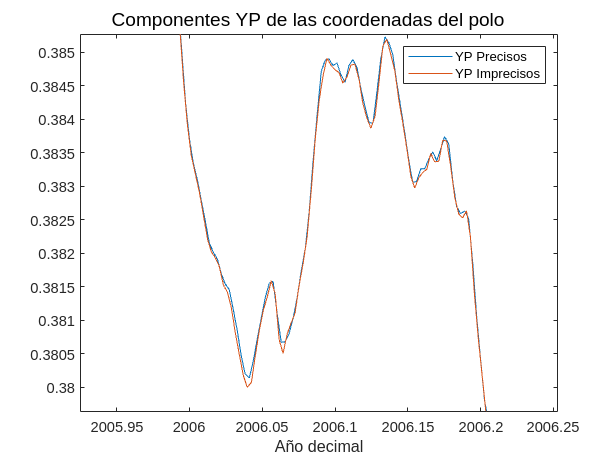

figure;
plot(tablaI.Fecha,tablaI.Y)
hold on
plot(tablaP.Fecha,tablaP.Y)
legend("YP Precisos","YP Imprecisos")
xlabel('Año decimal')
sgtitle('Componentes YP de las coordenadas del polo')
hold off
xlim([2005.925 2006.253])
ylim([0.37964 0.38527])

Como pasó anteriormente, si nos acercamos lo suficiente vemos pequeñas diferencias. 

### **Posiciones del polo X e Y**

Ahora comparamos las posiciones X e Y del polo, no hay variación aparente.

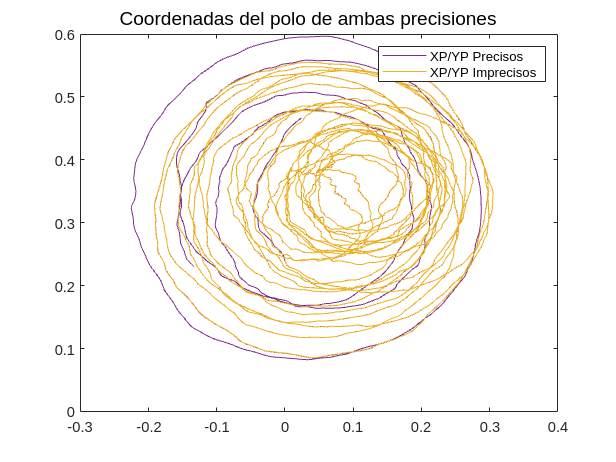

figure;
plot(tablaI.X,tablaI.Y,'Color',[0.4940 0.1840 0.5560])
hold on
plot(tablaP.X,tablaP.Y,'Color',[0.9290 0.6940 0.1250])
legend("XP/YP Precisos","XP/YP Imprecisos")
sgtitle('Coordenadas del polo de ambas precisiones')
hold off

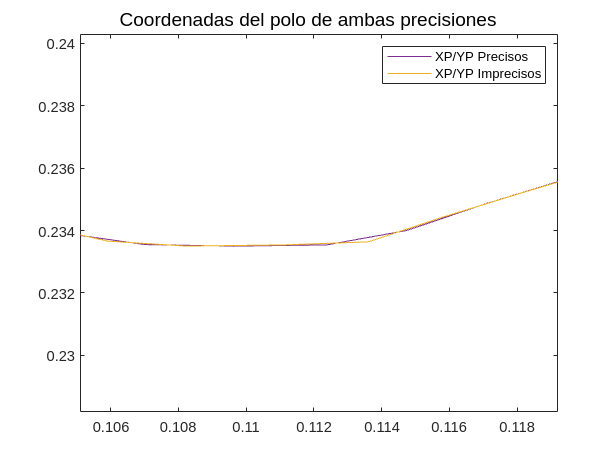


figure;
plot(tablaI.X,tablaI.Y,'Color',[0.4940 0.1840 0.5560])
hold on
plot(tablaP.X,tablaP.Y,'Color',[0.9290 0.6940 0.1250])
legend("XP/YP Precisos","XP/YP Imprecisos")
sgtitle('Coordenadas del polo de ambas precisiones')
hold off
xlim([0.1051 0.1192])
ylim([0.2282 0.2403])

Y como era de esperar, al unir las gráficas donde estén X e Y siguen habiendo diferencias al acercarnos lo suficiente.

### Variación UT1-UTC respecto del tiempo

En esta última gráfica la diferencia es más evidente, ya que en el inicio de ella hay un escalón de los datos precisos, así que podemos concluir que los otros datos no son tan acertados como los precisos.

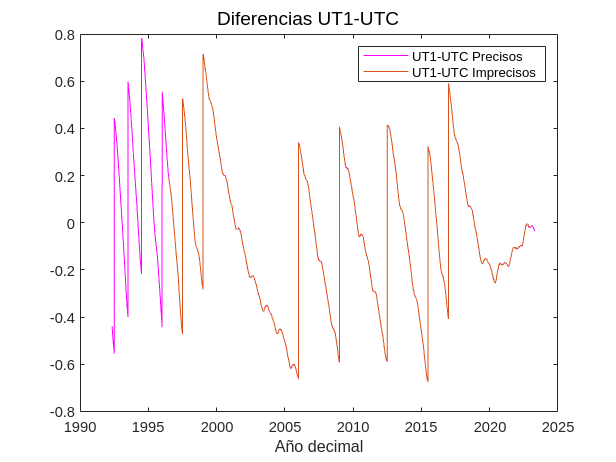

figure;
plot(tablaI.Fecha,tablaI.UT,"magenta")
hold on
plot(tablaP.Fecha,tablaP.UT)
legend("UT1-UTC Precisos","UT1-UTC Imprecisos")
xlabel('Año decimal')
sgtitle('Diferencias UT1-UTC')
hold off

Aqui obsaervamos las irregularidades.

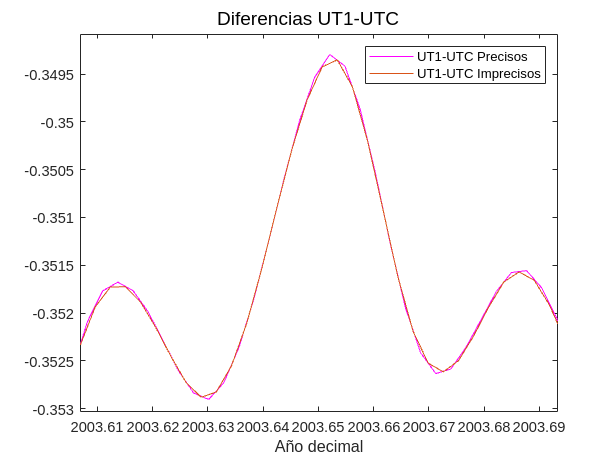

figure;
plot(tablaI.Fecha,tablaI.UT,"magenta")
hold on
plot(tablaP.Fecha,tablaP.UT)
legend("UT1-UTC Precisos","UT1-UTC Imprecisos")
xlabel('Año decimal')
sgtitle('Diferencias UT1-UTC')
hold off

xlim([2003.6069 2003.6933])
ylim([-0.35303 -0.34908])

*Adrián Fernández Tejada - Adrián Sánchez Loureiro*